S1: Top-switch of  first module

S2:  Bottom-switch of first module

S3 : Top-switch of  second module

S4 : Bottom-switch of  second module

Phase-shift between S1 and S2 = 180 degree

Alpha: phase-shift between S1 and S3

D: Duty cycle of all switches 

## 0< alpha/360 < D

alpha=20;
D=0.2;
time=[0, (alpha/360), D, (alpha/360)+D, 0.5, 0.5+ (alpha/360), 0.5+D ...
    0.5+(alpha/360)+D, 1] 

time =          0    0.0556    0.2000    0.2556    0.5000    0.5556    0.7000    0.7556    1.0000


S1=[1 1 0 0 0 0 0 0 0]

S1 =      1     1     0     0     0     0     0     0     0


S2=[0 0 0 0 1 1 0 0 0]

S2 =      0     0     0     0     1     1     0     0     0


S3=[0 1 1 0 0 0 0 0 0]

S3 =      0     1     1     0     0     0     0     0     0


S4=[0 0 0 0 0 1 1 0 0]

S4 =      0     0     0     0     0     1     1     0     0


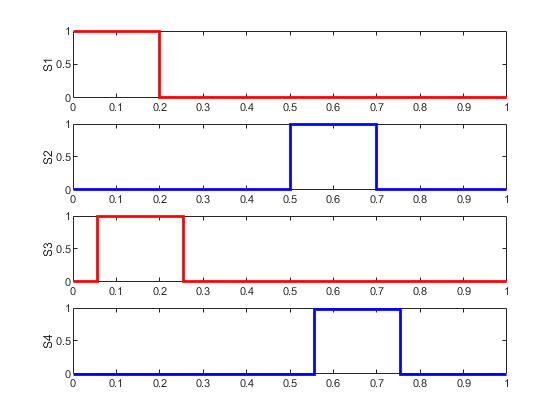

figure();
subplot(4,1,1)
stairs(time,S1,'color','r','LineWidth',2)
ylabel('S1')
subplot(4,1,2)
stairs(time,S2,'color','b','LineWidth',2)
ylabel('S2')
subplot(4,1,3)
stairs(time,S3,'color','r','LineWidth',2)
ylabel('S3')
subplot(4,1,4)
stairs(time,S4,'color','b','LineWidth',2)
ylabel('S4')


Vo=1;
Vin=Vo*ones(1,9)*(1-D);
Vgo=(Vo/2*(S1+S2+S3+S4))/4;
figure();
subplot(4,1,1)
stairs(time,Vgo,'color','r','LineWidth',2)
Vcm=(Vo/2)*(S1+S3)/2

Vcm =     0.2500         0    0.2500         0         0         0         0         0         0


Vdm=(Vo/2)*(S1-S3)/2

Vdm =     0.2500         0   -0.2500         0         0         0         0         0         0


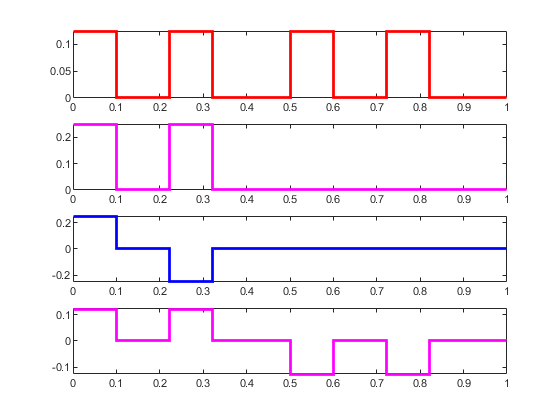

subplot(4,1,2)
stairs(time,Vcm,'color','m','LineWidth',2)
subplot(4,1,3)
stairs(time,Vdm,'color','b','LineWidth',2)
subplot(4,1,4)
stairs(time,Vcm-Vgo,'color','m','LineWidth',2)

## alpha/360 > D

alpha=80;
D=0.1;
time=[0, D, (alpha/360), (alpha/360)+D, 0.5, 0.5+ D, 0.5+(alpha/360) ...
    0.5+(alpha/360)+D, 1] 

time =          0    0.1000    0.2222    0.3222    0.5000    0.6000    0.7222    0.8222    1.0000


S1=[1 0 0 0 0 0 0 0 0]

S1 =      1     0     0     0     0     0     0     0     0


S2=[0 0 0 0 1 0 0 0 0]

S2 =      0     0     0     0     1     0     0     0     0


S3=[0 0 1 0 0 0 0 0 0]

S3 =      0     0     1     0     0     0     0     0     0


S4=[0 0 0 0 0 0 1 0 0]

S4 =      0     0     0     0     0     0     1     0     0


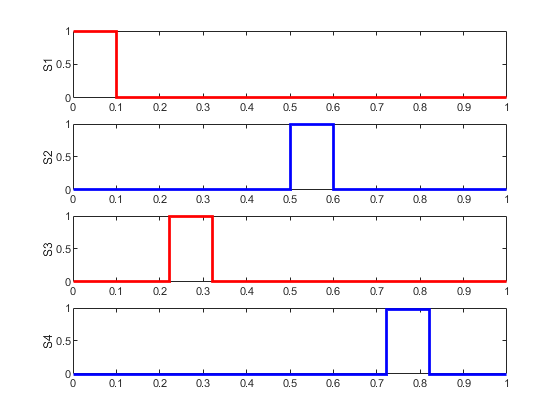

figure();
subplot(4,1,1)
stairs(time,S1,'color','r','LineWidth',2)
ylabel('S1')
subplot(4,1,2)
stairs(time,S2,'color','b','LineWidth',2)
ylabel('S2')
subplot(4,1,3)
stairs(time,S3,'color','r','LineWidth',2)
ylabel('S3')
subplot(4,1,4)
stairs(time,S4,'color','b','LineWidth',2)
ylabel('S4')

Vo=1;
Vin=Vo*ones(1,9)*(1-D);
Vgo=(Vo/2*(S1+S2+S3+S4))/4;
figure();
subplot(4,1,1)
stairs(time,Vgo,'color','r','LineWidth',2)
Vcm=(Vo/2)*(S1+S3)/2

Vcm =     0.2500         0    0.2500         0         0         0         0         0         0


Vdm=(Vo/2)*(S1-S3)/2

Vdm =     0.2500         0   -0.2500         0         0         0         0         0         0


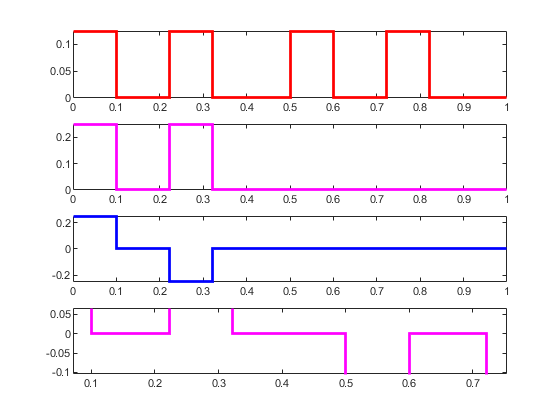

subplot(4,1,2)
stairs(time,Vcm,'color','m','LineWidth',2)
subplot(4,1,3)
stairs(time,Vdm,'color','b','LineWidth',2)
subplot(4,1,4)
stairs(time,Vcm-Vgo,'color','m','LineWidth',2)

Vo=1;
Vin=Vo*ones(1,9)*(1-D);
Vgo=(Vo/2*(S1+S2+S3+S4))/4;
figure();
subplot(4,1,1)
stairs(time,Vgo,'color','r','LineWidth',2)
Vcm=(Vo/2)*(S2+S4)/2

Vcm =          0         0         0         0    0.2500         0    0.2500         0         0


Vdm=(Vo/2)*(S2-S4)/2

Vdm =          0         0         0         0    0.2500         0   -0.2500         0         0


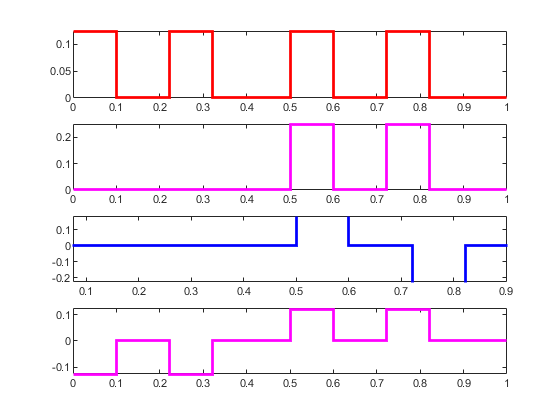

subplot(4,1,2)
stairs(time,Vcm,'color','m','LineWidth',2)
subplot(4,1,3)
stairs(time,Vdm,'color','b','LineWidth',2)
subplot(4,1,4)
stairs(time,Vcm-Vgo,'color','m','LineWidth',2)